# Problem 6.4

## a

There are essentially two loops in this control system. The inner loop can me modeled as a feedback compensator with $H\left(z\right)=B\;2\frac{z-1\;}{z+1}$, for $h=1$.

The digitized double integrator has a transfer function $\tilde{G} \left(z\right)=\frac{\left(z+1\right)}{2{\left(z-1\right)}^2 }$. So the transfer function of the inner loop, is $\frac{K\tilde{\;G} }{1+K\tilde{G} H}=\frac{\frac{\;K}{2}\left(z+1\right)\left(z-1\right)}{z+\left(KB-1\right)}$. Let's call this $G_{\mathrm{new}} \left(z\right)$ and ignore the fact that it is not realizable for now.

The outer loop is a unity feedback loop. So the overall system is simply $T\left(z\right)=\frac{K\left(z^2 -1\right)}{\;{Kz}^2 +2z+\left(2KB-2-K\right)}$. After performing the Jury Test, we have two conditions for stability: $K>0,\;\frac{K^2 -{\left(2KB-2-K\right)}^2 }{K}>0$. 

Update: Forgot the factor of $\frac{1}{2}$ in the numerator of $\tilde{G} \left(z\right)$ initially when doing Jury test, which may add more conditions to the Jury test for stability. 

## b

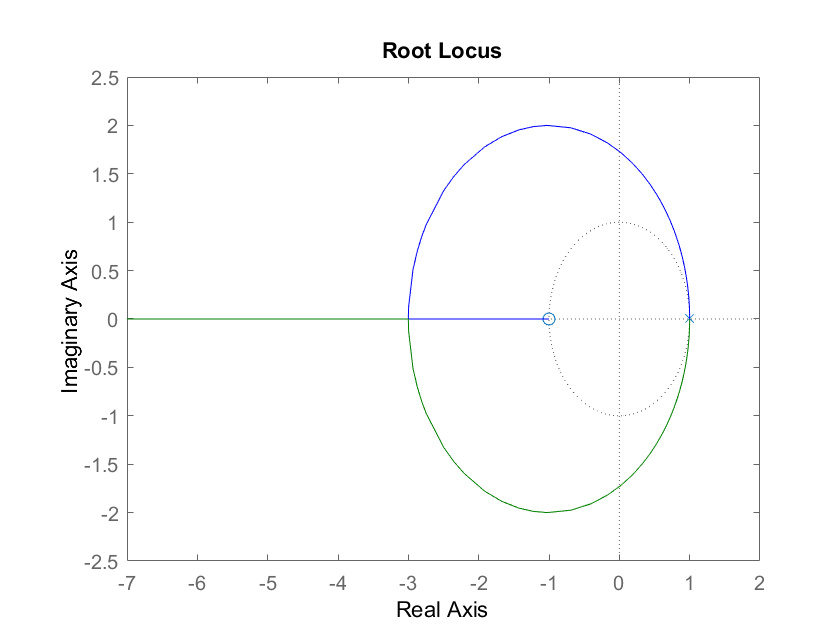

h = 1;
z = tf('z', 1);
Gz = (h^2)*0.5*(z+1)/(z-1)^2;
% Beta = 0
rlocus(Gz);

There are no values of K where CL system is valid with $B=1$.

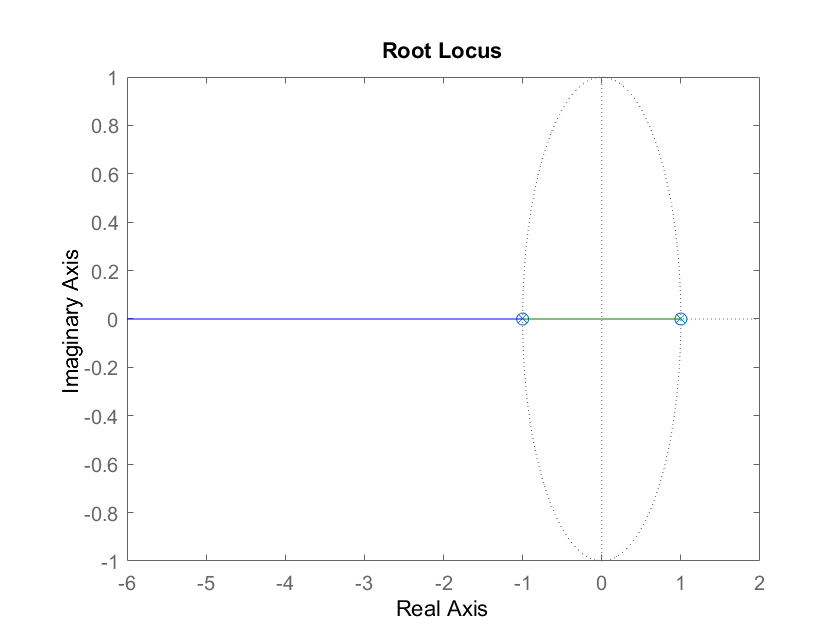

% Beta = 3/2
h = 1;
z = tf('z', h);
Hz = (3/2)*(2/h)*(z-1)/(z+1);
LG = Gz*Hz;
rlocus(LG);

With $B=\frac{3}{2}$, CL system is stable for $K<~1\ldotp 33$.

## c

Uncomment the code and run the desired K value to be used.

K = 0.5;
% K = 1;
% K = 1.25;
NS = 4;
h = 1;
h_sim = h/NS;
h = h_sim;
beta = 3/2;
z = tf('z', h_sim);
s = tf('s');
Gz_sim = (h^2)*0.5*(z+1)/(z-1)^2;
Gs_sim = 1/s^2;
Hz_sim = beta*(2/h)*(z-1)/(z+1);
Hs_sim = beta*s;
G_new_sim = feedback(K*Gz_sim, Hz_sim);
Gs_new_sim = feedback(K*Gs_sim, Hs_sim);
Tz = feedback(G_new_sim, 1);
Ts = feedback(Gs_new_sim, 1);
t = -10:h_sim:10;
u = 1.5+ heaviside(t);
figure;
lsim(Tz, u, t)

hold on;
lsim(Ts, u, t);

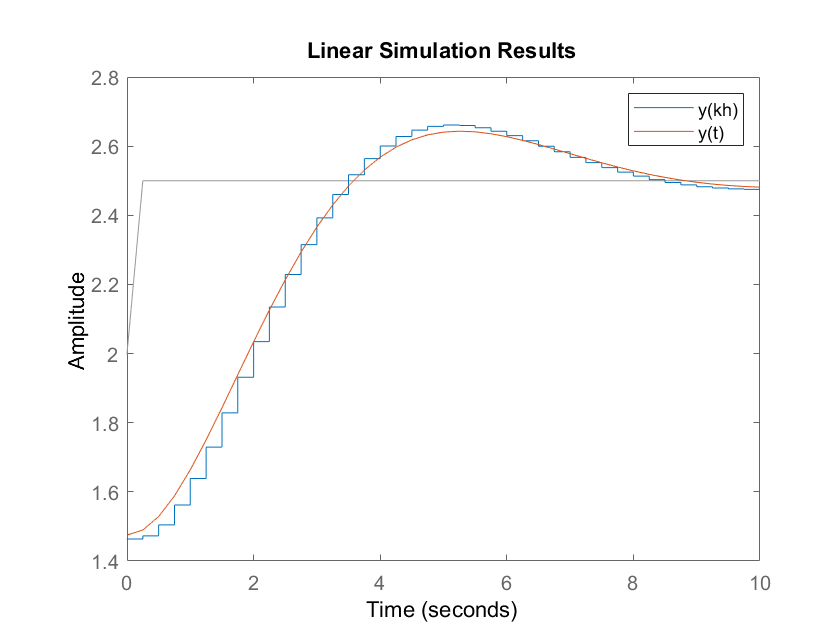

legend('y(kh)','y(t)')
xlim([0 10]);
hold off;

As K increases, it appears that the system's response becomes more stable. This is surprising, considering that the system should become unstable for K>1.33. This might have something to do with the zero located at z+1. More likely, it is due to an error somewhere in the code.